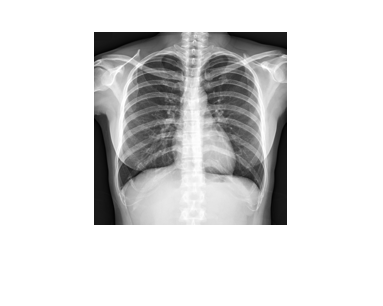

f=imread('radiograph1.jpg');
f=double(f(:,:,1));
f=f/max(max(f));
f=imresize(f,0.15);
figure(1)
imshow(f,[]);

## Thresholding

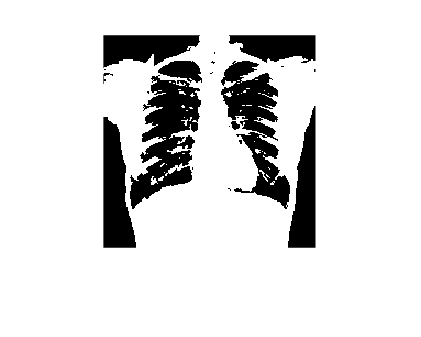

seg1 = f > 0.5;
imshow(seg1,[])

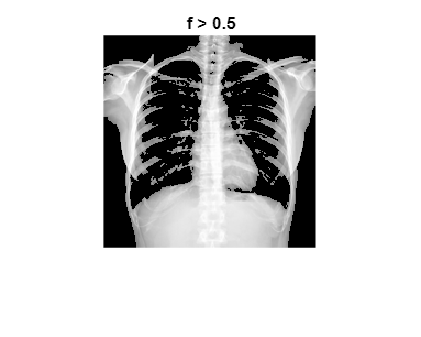

imshow(seg1.*f,[])
title(' f > 0.5')

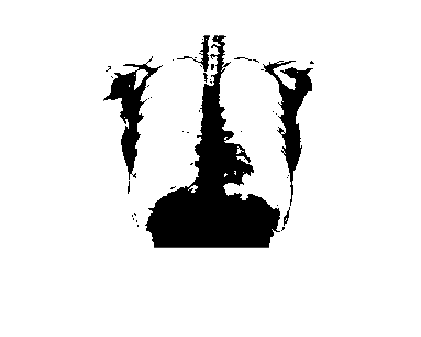

seg1 = f < 0.75;
imshow(seg1,[])

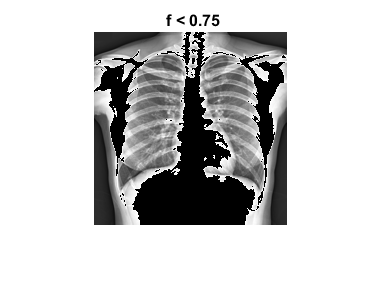

imshow(seg1.*f,[])
title(' f < 0.75')

seg = f > 0.4;
imshow(seg1, [])

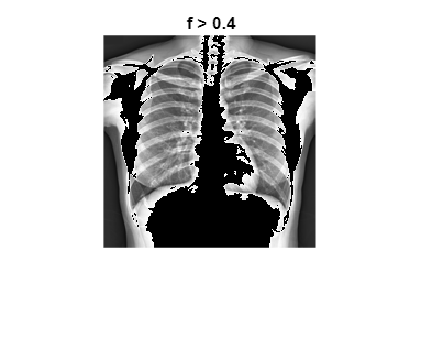

imshow(seg1.*f, [])
title(' f > 0.4')

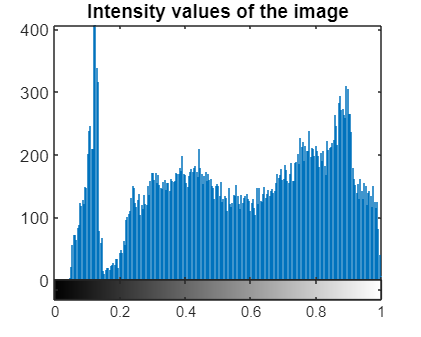

imhist(f)
title('Intensity values of the image')

% Use a third threshold based on the histogram

## Otsu method

thr = graythresh(f)

thr = 0.5490

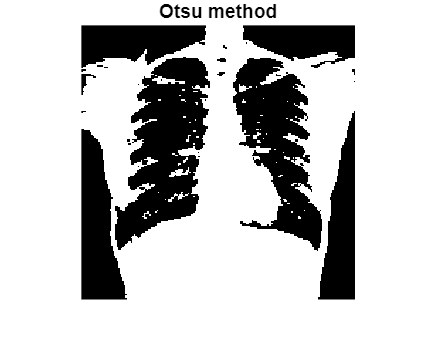

seg1 = f > thr;
imshow(seg1,[])
title('Otsu method')

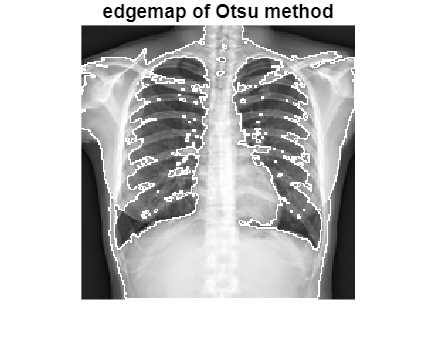

dxp=[0,1;-1,0];
dyp=[1,0;0,-1];
edgemap = abs(conv2(seg1,dxp,'same'))+abs(conv2(seg1,dyp,'same'));
imshow(f+edgemap,[0,1]);
title('edgemap of Otsu method')


% Compare the otsu provided threshold vs the one you selected in the
% preview step.
% Do you trust the Otsu treshold? 
% A = this method obtains the numerical value of the intensity scale in
% which the gray color appears. Taking that into account, we see in the
% image obtained with the Otsu method that we can appreciate most of the
% tissue appearing on the radiography.
%
% Select your own image and compute the otsu threshold

## Kmeans segmentation

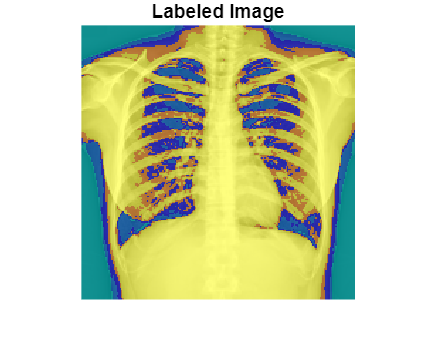

[L,Centers] = imsegkmeans(int8(255*f),5);
B = labeloverlay(f,L);
imshow(B)
title("Labeled Image")

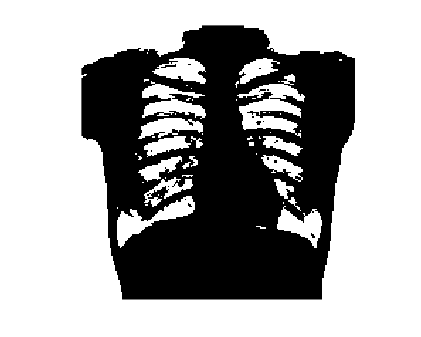

imshow(int8(255*f)<Centers(1),[])

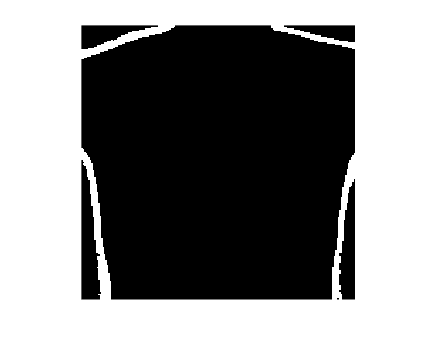

imshow(int8(255*f)<Centers(2),[])

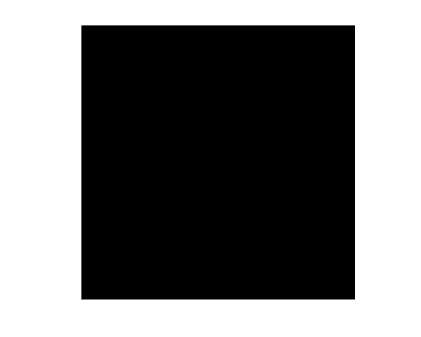

imshow(int8(255*f)>Centers(3),[])

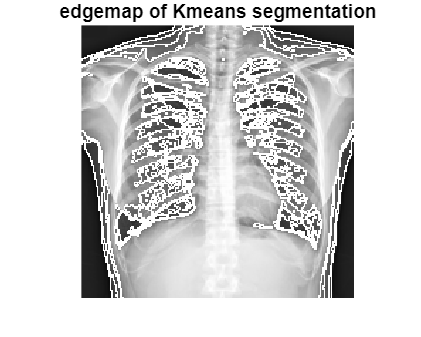

edgemap = abs(conv2(L,dxp,'same'))+abs(conv2(L,dyp,'same'));
imshow(f+edgemap,[0,1]);
title('edgemap of Kmeans segmentation')


% Do the same procedure but now with 5 centers.
% Is the segmentation better?
% By separating the image in 5 klusters, we can observe a clear difference
% in the labeled image, resulting in an image having a better quality and
% resolution. The edgemap of the image also appears to have more definition
% and be more detailed.

## Watershed segmentation

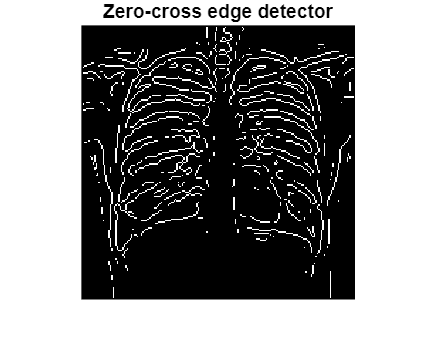

edgeC = edge(f,'zerocross');
imshow(edgeC,[])
title('Zero-cross edge detector')

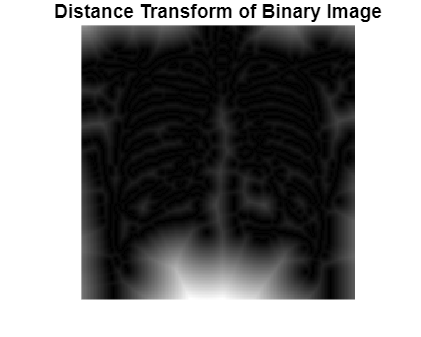

D = bwdist(edgeC);
imshow(D,[])
title('Distance Transform of Binary Image')

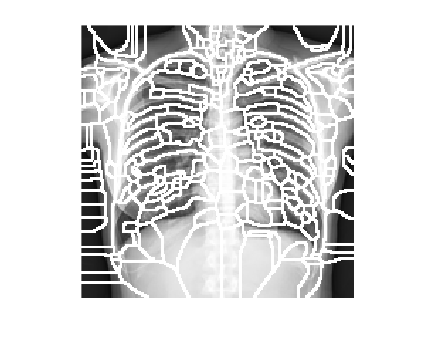

L = watershed(D);

edgemap = abs(conv2(L,dxp,'same'))+abs(conv2(L,dyp,'same'));
imshow(f+edgemap,[0,1]);




L(edgeC) = 0;

Display the resulting label matrix as an RGB image.

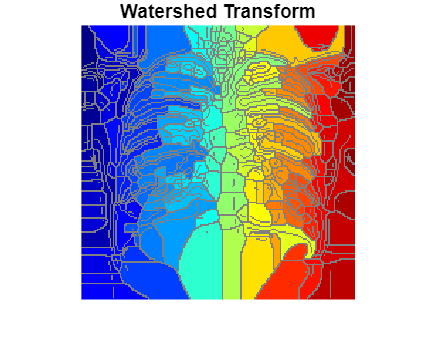

rgb = label2rgb(L,'jet',[.5 .5 .5]);
imshow(rgb)
title('Watershed Transform')


% provide an alterante segmentation based on a different edge detector